## Loading the data set

% Setting format
format long g 

% Loading the dataset
data = readtimetable("DatiProject.xlsx","Sheet","Data");

#### Creating variables for the analysis

% log(GDP)
data.log_gdp = log(data.GDPC1);

% First difference of log(GDP)
data.del_y = [0; diff(data.log_gdp)];

% Inflation
data.infl = [0; diff(log(data.PCECTPI))];

% Creating spread
data.spread = data.GS10 - data.TB3MS;

data

data = 254×8 timetable
       Time         GDPC1      PCECTPI    TB3MS      GS10         log_gdp                del_y                    infl             spread
    ___________    ________    _______    ______    ______    ________________    ____________________    _____________________    ______

    30-Jun-1960    3430.057    15.331       3.54    4.5033    8.14033215809771                       0                        0    0.9633
    30-Sep-1960    3439.832    15.415       4.23    4.5833    8.14317791196557     0.00284575386785768      0.00546413900979648    0.3533
    30-Dec-1960    3517.181    15.435     3.8733    4.4867    8.165

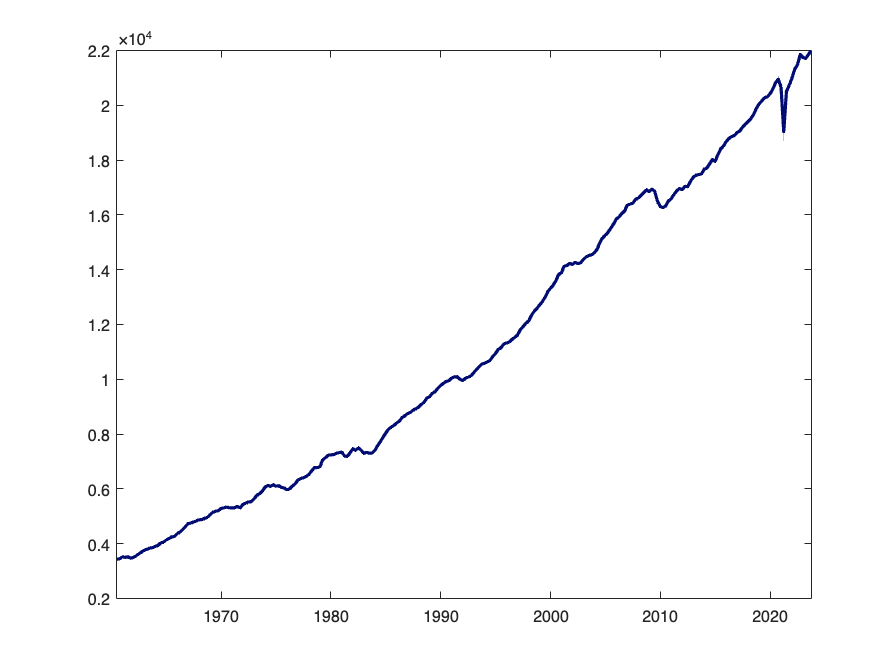

plot(data.Time, data.GDPC1, "LineWidth",2, color="#010d73");

## Random Walk model

% Vector to save the forecasts
rw_forecast = NaN(134,1);

% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting
while i <= 134

    % Model estimation 
    rw = estimate(arima("D",1,"Constant",0), data.log_gdp(i:i+99),"Display","off");
    % 1-step ahead forecast
    rw_forecast(i) = forecast(rw,1,data.log_gdp(i:i+99)); 
    % Moving the rolling window
    i = i + 1;

end

% Exponentiation to obtain the level forecast
rw_forecast = exp(rw_forecast);

% RMSE of the level forecast
rw_rmse = rmse(rw_forecast, data.GDPC1(101:234))

rw_rmse =           119.438277095983


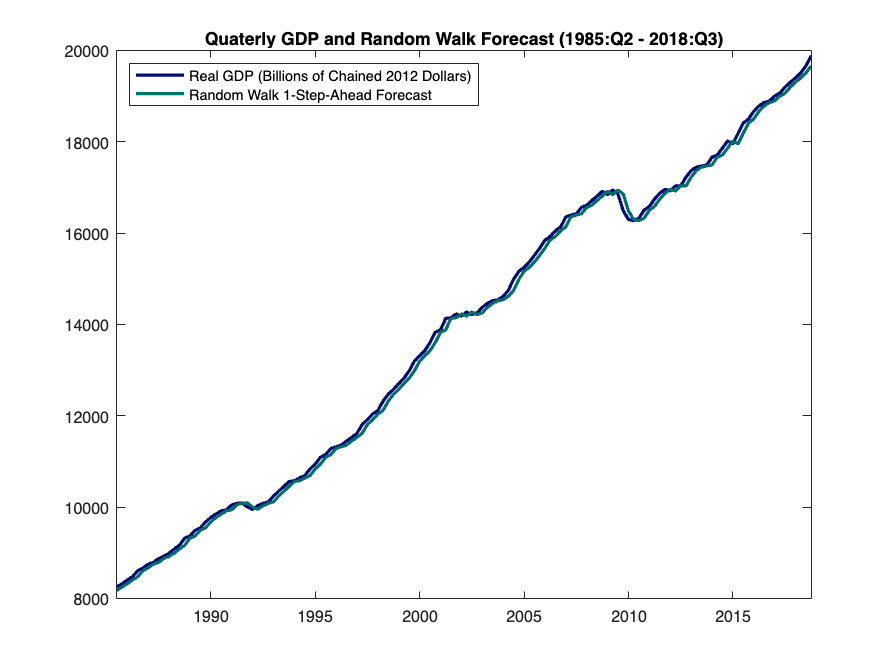

% Random Walk forecast plot
clf("reset")
rw_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), rw_forecast, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "Random Walk 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and Random Walk Forecast (1985:Q2 - 2018:Q3)")
hold off;

## AR(4) model

% Vector to save the forecasts
ar_forecast = NaN(134,1);

% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting
while i <= 134

    % Model estimation 
    ar = estimate(arima(4, 1, 0), data.log_gdp(i:i+99),"Display","off");
    % 1-step ahead forecast
    ar_forecast(i) = forecast(ar, 1, data.log_gdp(i:i+99));
    % Moving the rolling window
    i = i + 1;

end

% Exponentiation to obtain the level forecast
ar_forecast = exp(ar_forecast);

% RMSE of the level forecast
ar_rmse = rmse(ar_forecast, data.GDPC1(101:234))

ar_rmse =           79.4732756099896


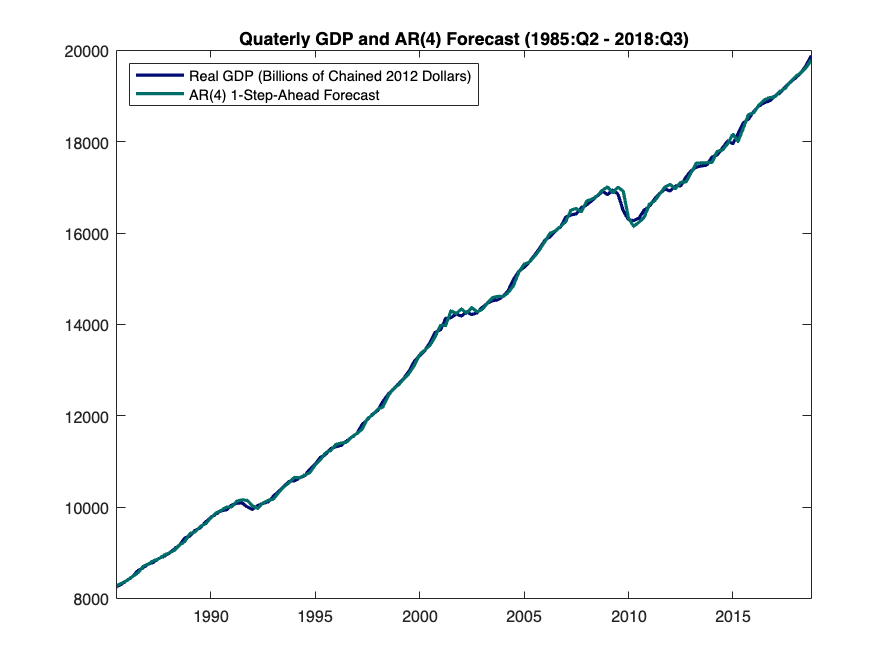

% Random Walk forecast plot
clf("reset")
ar_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), ar_forecast, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "AR(4) 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and AR(4) Forecast (1985:Q2 - 2018:Q3)")
hold off;

## VAR(4)

### ACF Plots:

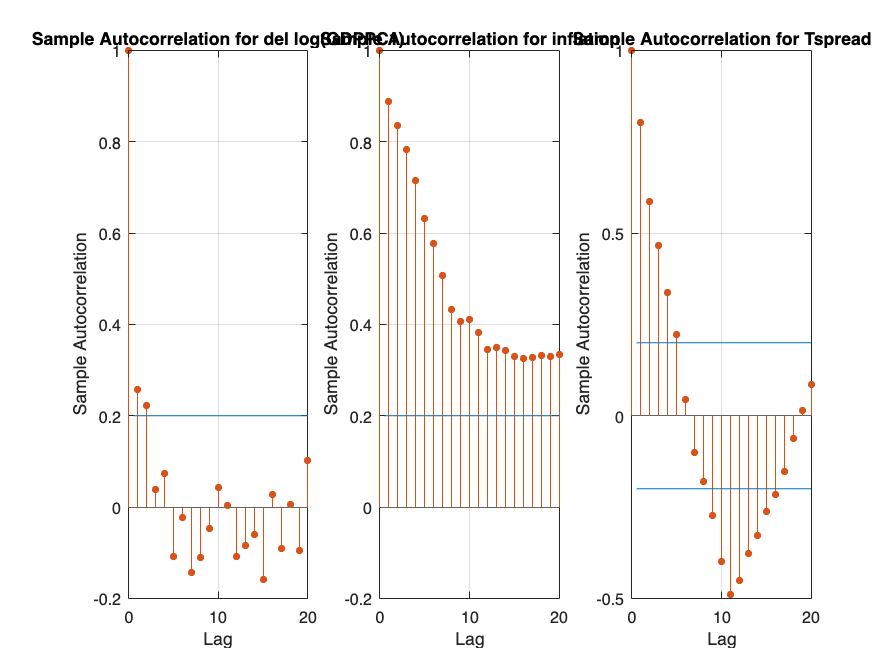

% ACF del log(GDP)
figure
subplot(1,3,1)
autocorr(data.del_y(1:100))
title("Sample Autocorrelation for del log(GDPPC1)")
% ACF Inflation
subplot(1,3,2)
autocorr(data.infl(1:100))
title("Sample Autocorrelation for inflation")
% ACF Spread
subplot(1,3,3)
autocorr(data.spread(1:100))
title("Sample Autocorrelation for Tspread")

### Building the model

% Table containing the three series for the model
Y = data(:, ["del_y", "infl", "spread"]);

% Matrix to save the forecasts
var_forecast = NaN(134,3);
% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting
while i <= 134

    % Estimation the model
    var_model = estimate(varm(3, 4), Y(i:i+99, :),"Display","off");
    % 1-step ahead forecast
    var_forecast(i, 1:3) = table2array(forecast(var_model, 1, Y(i:i+99, :)));
    % Moving the rolling window
    i = i + 1;

end

% Going from change forecast to log(GDP) forecast
var_forecast_log_gdp = var_forecast(:, 1) + data.log_gdp(100:233);

% Exponentiation to obtain the level forecast
var_forecast_gdp = exp(var_forecast_log_gdp);

% RMSE of the level forecast
var_gdp_rmse = rmse(var_forecast_gdp, data.GDPC1(101:234))

var_gdp_rmse =           93.3839909497537


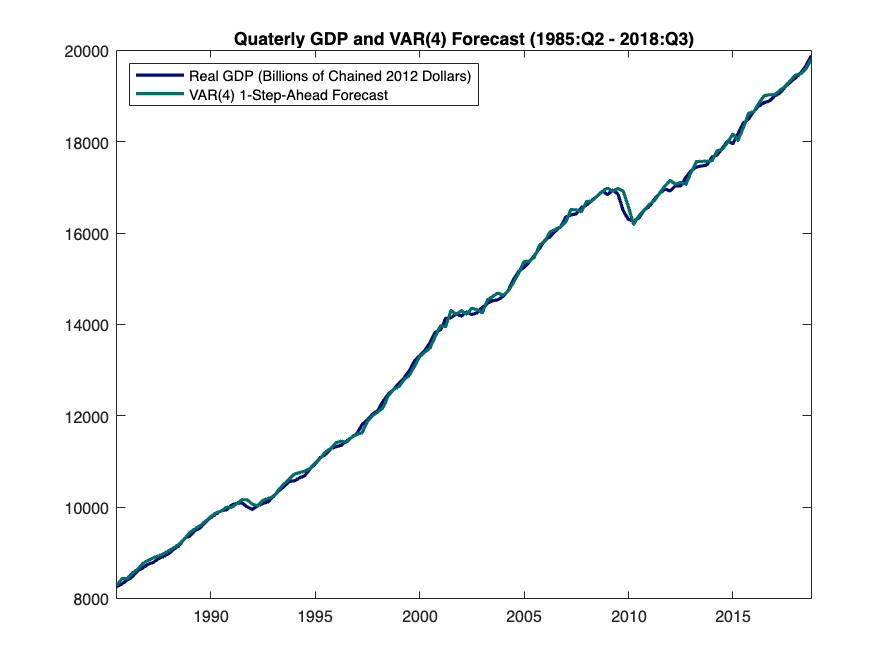

% VAR(4) GDP forecast plot
clf("reset")
var_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), var_forecast_gdp, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "VAR(4) 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and VAR(4) Forecast (1985:Q2 - 2018:Q3)")
hold off;

### Residuals of the VAR(4) forecast

% Creating vectors containing the residuals
del_y_res = Y(101:234,1) - var_forecast(:,1);
infl_res = Y(101:234,2) - var_forecast(:,2);
spread_res = Y(101:234,3) - var_forecast(:,3);


#### del log(GDP)

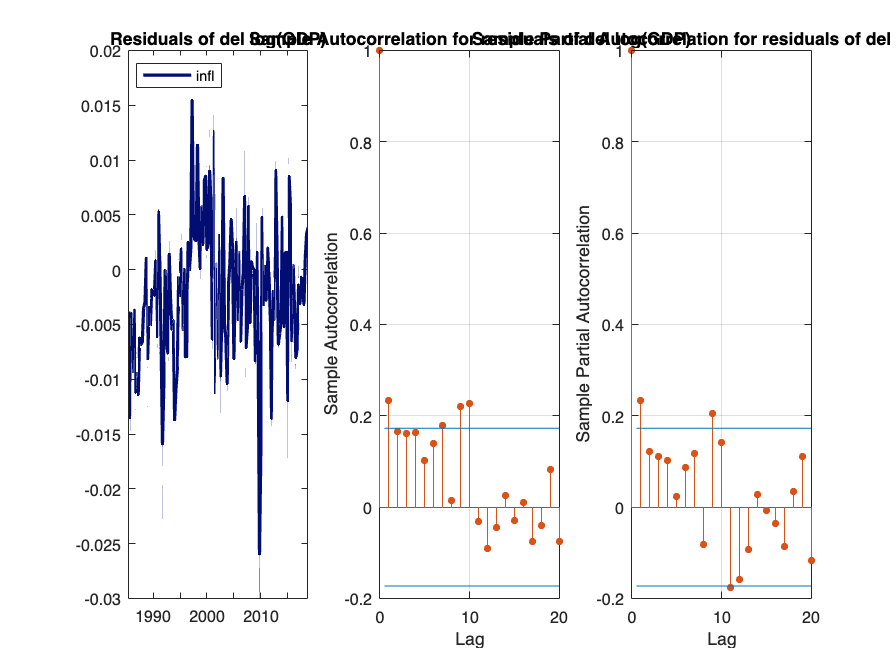

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, del_y_res.del_y, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of del log(GDP)")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(del_y_res)
title("Sample Autocorrelation for residuals of del log(GDP)")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(del_y_res)
title("Sample Partial Autocorrelation for residuals of del log(GDP)")

### Inflation

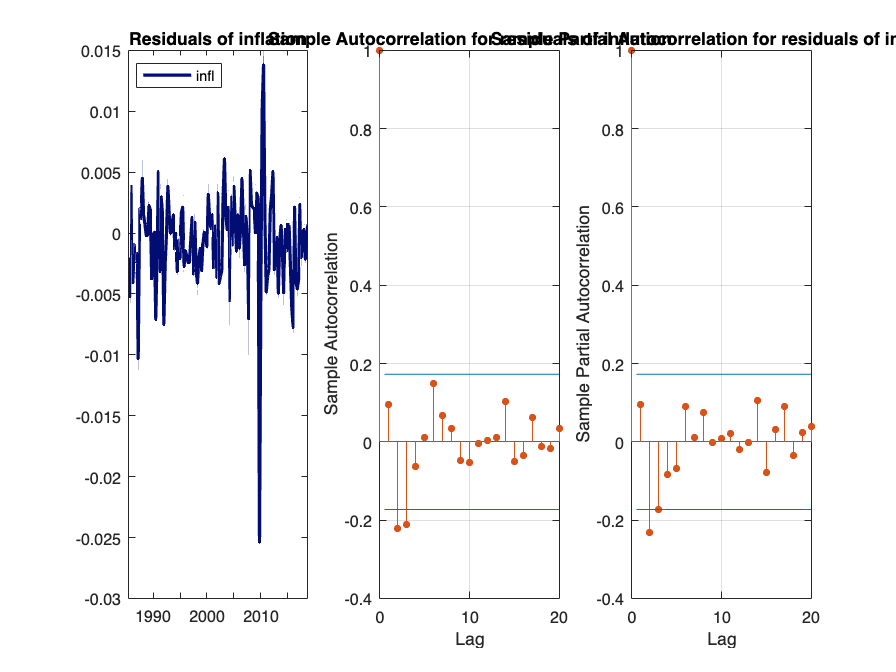

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, infl_res.infl, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of inflation")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(infl_res)
title("Sample Autocorrelation for residuals of inflation")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(infl_res)
title("Sample Partial Autocorrelation for residuals of inflation")

### Spread

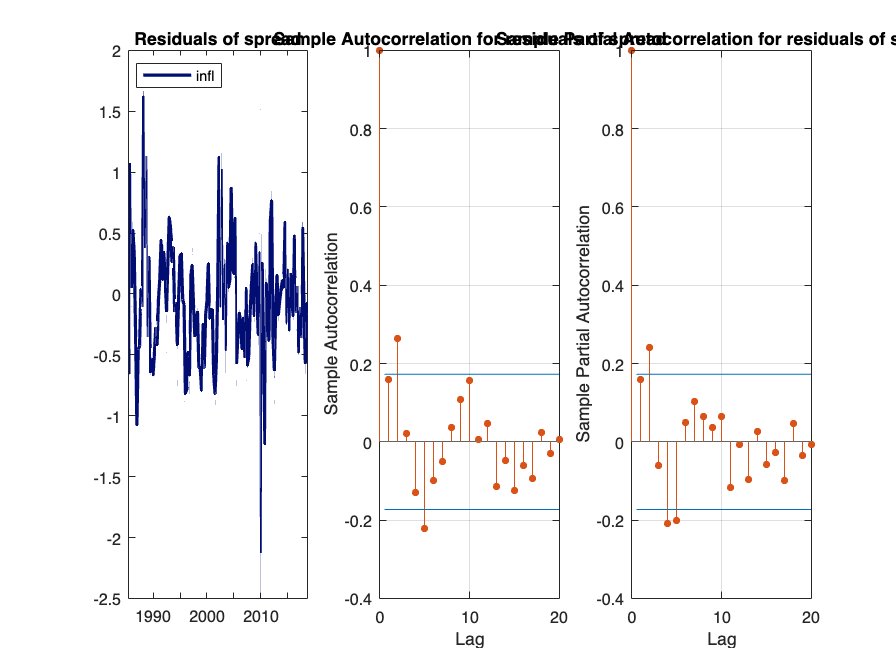

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, spread_res.spread, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of spread")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(spread_res)
title("Sample Autocorrelation for residuals of spread")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(spread_res)
title("Sample Partial Autocorrelation for residuals of spread")

## VAR(p) model

## in-sample residuals for 1st window

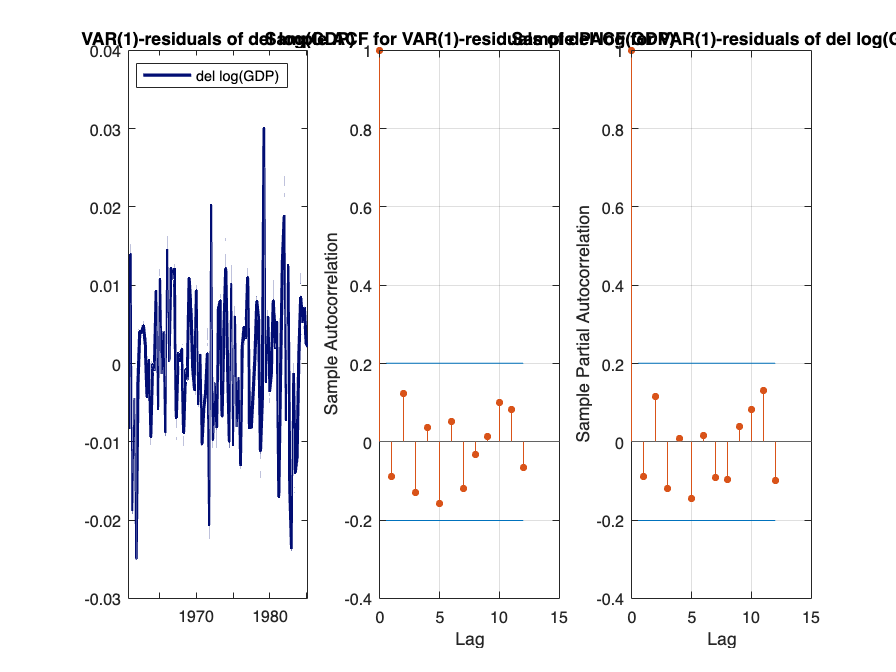

aics = NaN(12,1);

for p = 1:12

    var_p = estimate(varm(3, p), Y(1:100, :),"Display","off");
    aics(p) = summarize(var_p).AIC; 

end
p_opt = find(aics==min(aics));
[var_p_model,~,~,var_p_res] = estimate(varm(3, p_opt), Y(1:100, :),"Display","off");

clf("reset")
subplot(1,3,1)
plot(var_p_res.Time, var_p_res.del_y_Residuals, "LineWidth",2, color="#010d73");
legend({"del log(GDP)"}, "Location", "northwest")
title("VAR(1)-residuals of del log(GDP)")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(var_p_res.del_y_Residuals, NumLags=12)
title("Sample ACF for VAR(1)-residuals of del log(GDP)")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(var_p_res.del_y_Residuals, NumLags=12)
title("Sample PACF for VAR(1)-residuals of del log(GDP)")

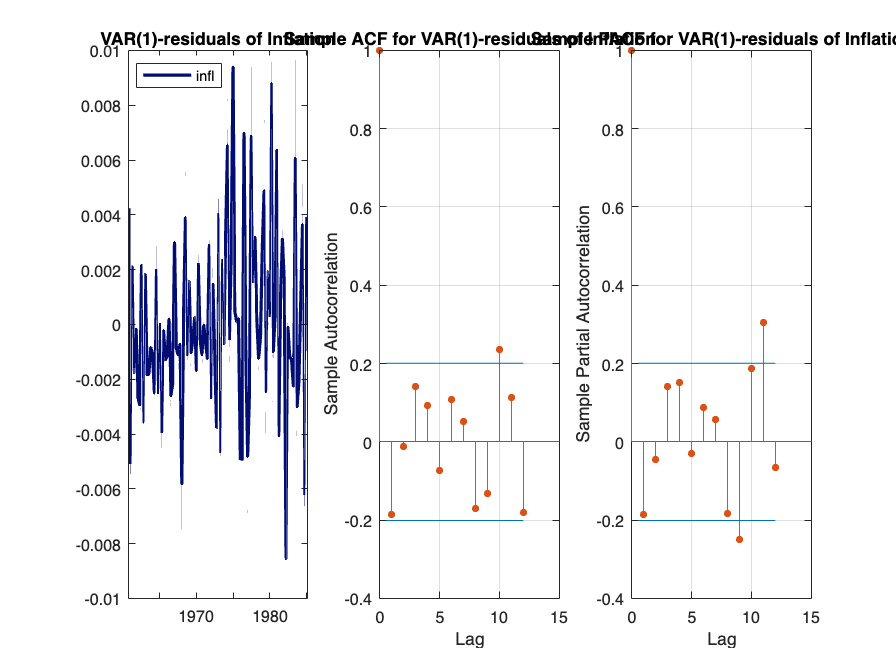


clf("reset")
subplot(1,3,1)
plot(var_p_res.Time, var_p_res.infl_Residuals, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("VAR(1)-residuals of Inflation")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(var_p_res.infl_Residuals, NumLags=12)
title("Sample ACF for VAR(1)-residuals of Inflation")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(var_p_res.infl_Residuals, NumLags=12)
title("Sample PACF for VAR(1)-residuals of Inflation")

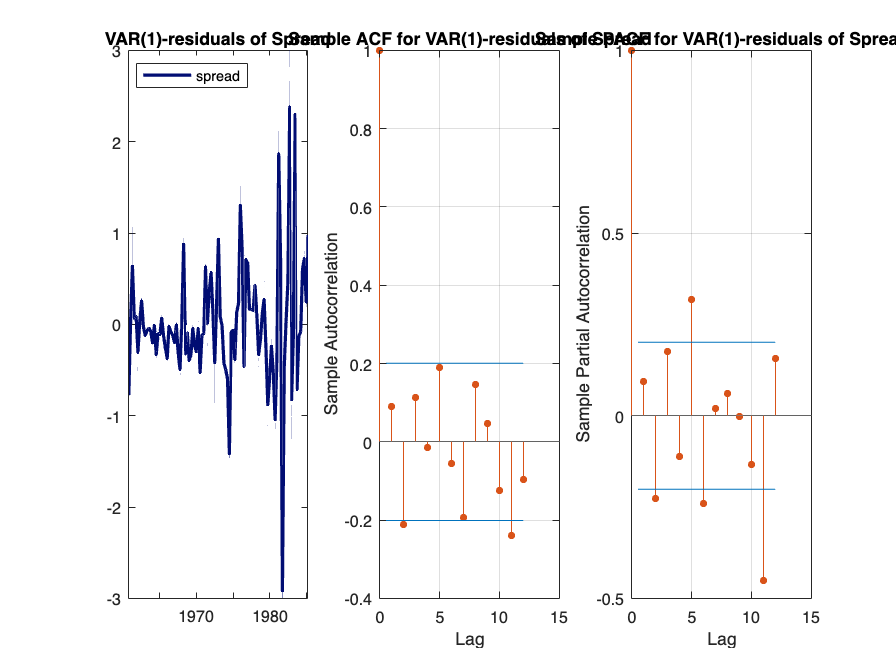


clf("reset")
subplot(1,3,1)
plot(var_p_res.Time, var_p_res.spread_Residuals, "LineWidth",2, color="#010d73");
legend({"spread"}, "Location", "northwest")
title("VAR(1)-residuals of Spread")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(var_p_res.spread_Residuals, NumLags=12)
title("Sample ACF for VAR(1)-residuals of Spread")
hold on;
% ACF of residuals of of del log(GDP)
subplot(1,3,3)
parcorr(var_p_res.spread_Residuals, NumLags=12)
title("Sample PACF for VAR(1)-residuals of Spread")

### Rolling Window Forecast

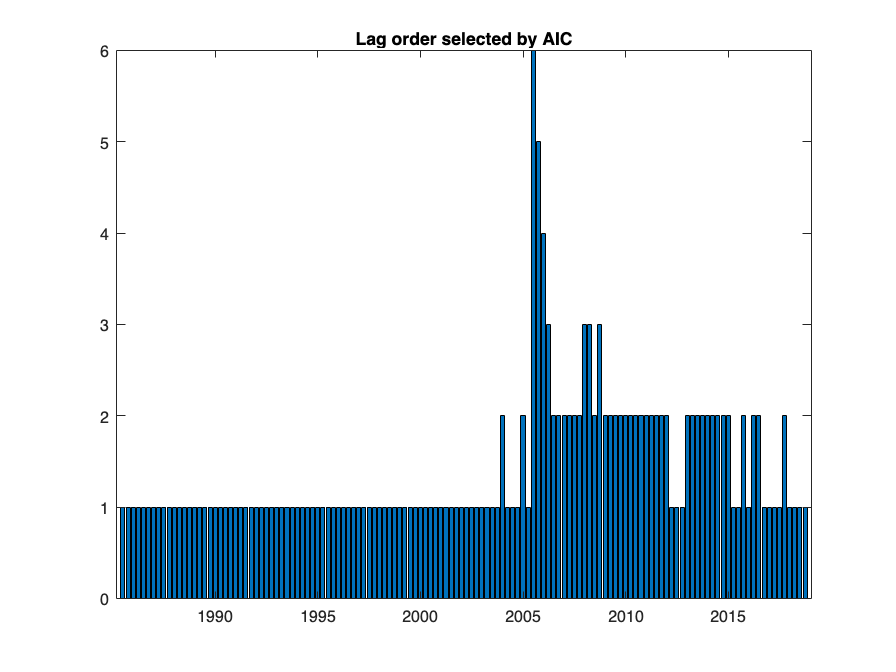

% Matrix to save the forecasts
var_p_forecast = NaN(134,3);

% Vector to save the number of lags selected in each period
lags = NaN(134,1);

% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting 
while i <= 134

    % Vector to save the AICs
    aics = NaN(12,1);
    
    % Estimating the model for all different lags and saving the AIC
    for p = 1:12

        var_p = estimate(varm(3, p), Y(i:i+99, :),"Display","off");
        aics(p) = summarize(var_p).AIC; 

    end
    
    % Choosing the number of lags with the lowest AIC
    p_opt = find(aics==min(aics));
    % Saving the chosen number of lags
    lags(i) = p_opt;

    % Estimating the model
    var_p_model = estimate(varm(3, p_opt), Y(i:i+99, :),"Display","off");
    % 1-step ahead forecast
    var_p_forecast(i, 1:3) = table2array(forecast(var_p_model, 1, Y(i:i+99, :)));
    % Moving the rolling window
    i = i + 1;

end 

clf("reset")
plot_lags = bar(data.Time(101:234), lags); 
title("Lag order selected by AIC")

% Going from change forecast to log(GDP) forecast
var_p_forecast_log_gdp = var_p_forecast(:, 1) + data.log_gdp(100:233);

% Exponentiation to obtain the level forecast
var_p_forecast_gdp = exp(var_p_forecast_log_gdp);

% RMSE of the level forecast
var_p_gdp_rmse = rmse(var_p_forecast_gdp, data.GDPC1(101:234))

var_p_gdp_rmse =            86.103350998666


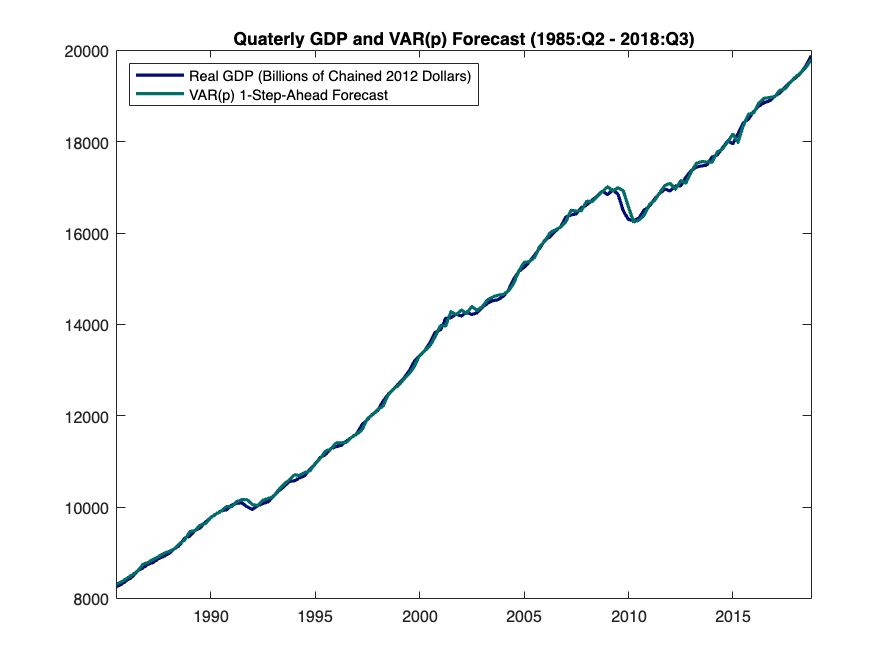

% VAR(p) GDP forecast plot
clf("reset")
ar_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), var_p_forecast_gdp, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "VAR(p) 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and VAR(p) Forecast (1985:Q2 - 2018:Q3)")
hold off;

### Residuals of the VAR(p) forecast

% Creating vectors containing the residuals
del_y_res = Y(101:234,1) - var_p_forecast(:,1);
infl_res = Y(101:234,2) - var_p_forecast(:,2);
spread_res = Y(101:234,3) - var_p_forecast(:,3);


#### del log(GDP)

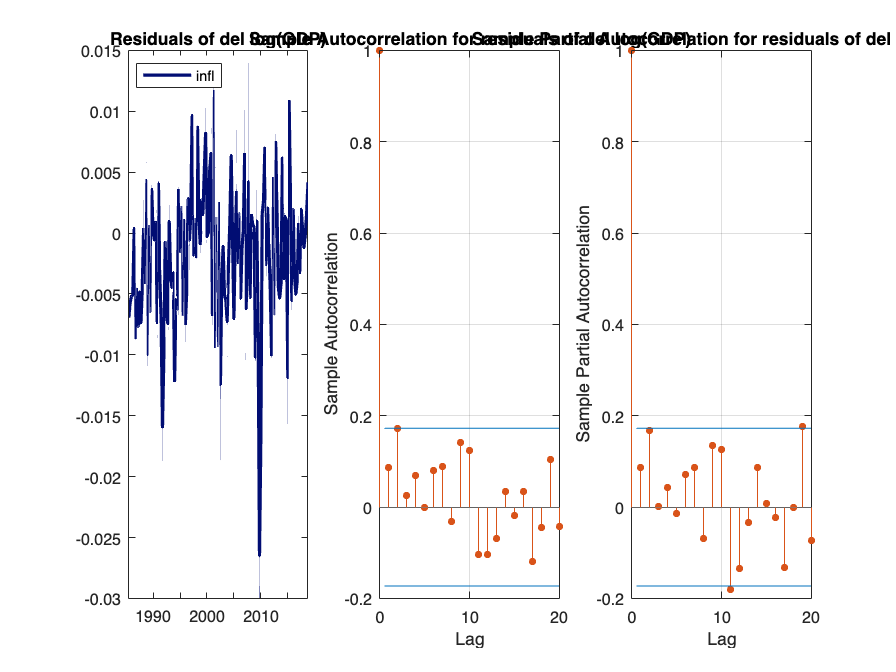

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, del_y_res.del_y, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of del log(GDP)")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,2)
autocorr(del_y_res)
title("Sample Autocorrelation for residuals of del log(GDP)")
hold on;
% ACF of residuals of del log(GDP)
subplot(1,3,3)
parcorr(del_y_res)
title("Sample Partial Autocorrelation for residuals of del log(GDP)")

### Inflation

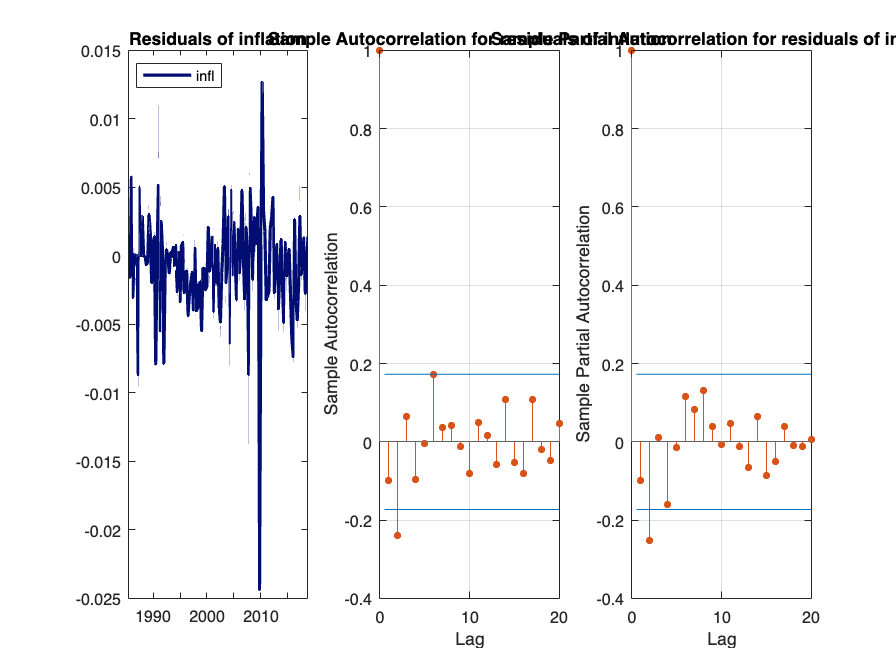

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, infl_res.infl, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of inflation")
hold on;
% ACF of residuals of inflation
subplot(1,3,2)
autocorr(infl_res)
title("Sample Autocorrelation for residuals of inflation")
hold on;
% ACF of residuals of inflation
subplot(1,3,3)
parcorr(infl_res)
title("Sample Partial Autocorrelation for residuals of inflation")

### Spread

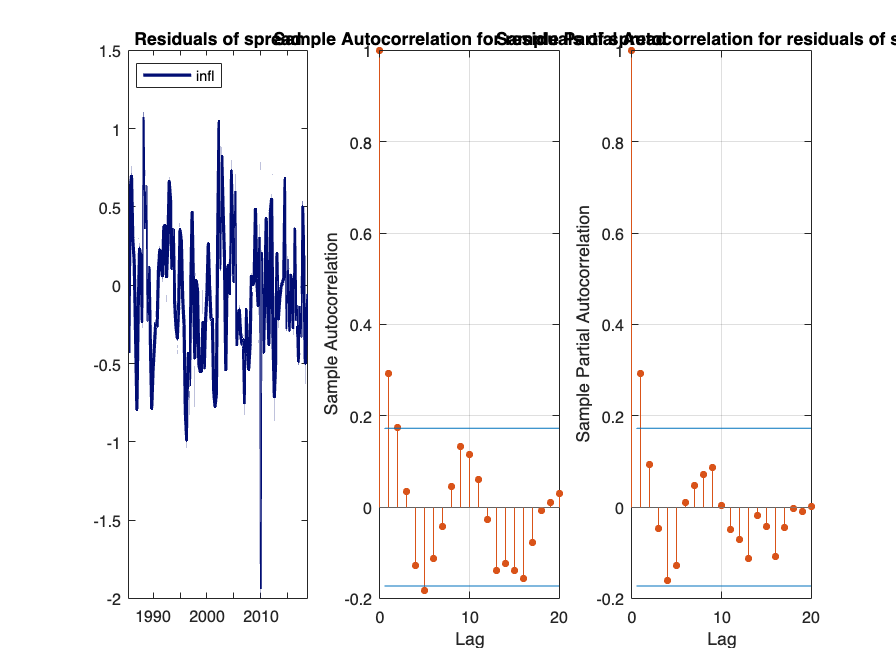

clf("reset")
subplot(1,3,1)
plot(del_y_res.Time, spread_res.spread, "LineWidth",2, color="#010d73");
legend({"infl"}, "Location", "northwest")
title("Residuals of spread")
hold on;
% ACF of spread
subplot(1,3,2)
autocorr(spread_res)
title("Sample Autocorrelation for residuals of spread")
hold on;
% PACF of spread
subplot(1,3,3)
parcorr(spread_res)
title("Sample Partial Autocorrelation for residuals of spread")

## AR(4)-X:

% Loading the data for the factors
factor_data = readtimetable("DatiProject.xlsx", "Sheet", "DataForFactors");

factor_data = timetable2table(factor_data);
factor_data = table2array(factor_data(:, 2:end));

### PC Plot

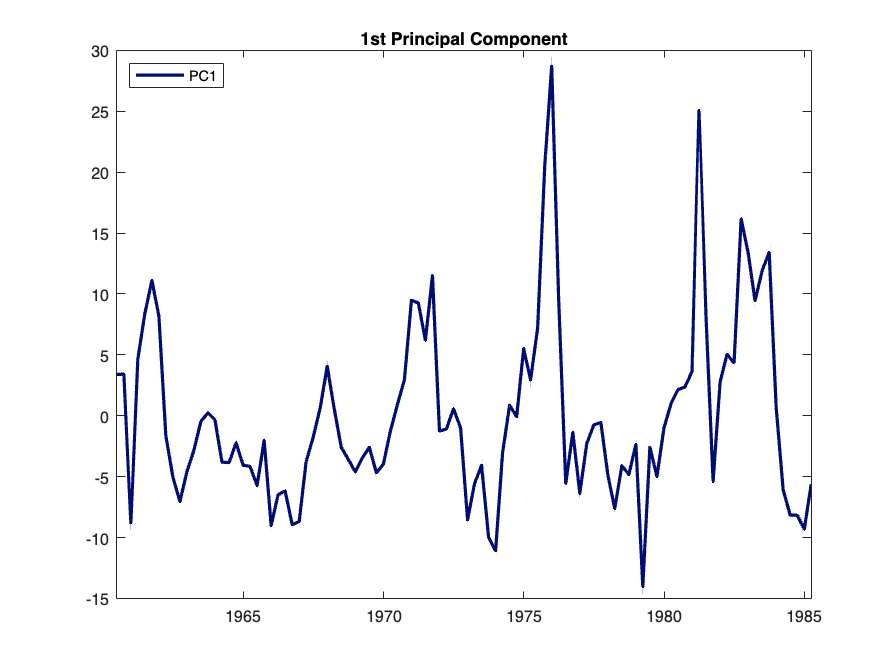

% Vector for the standardised factor data
factors_standardised = NaN(100, 245);
    
% Standardising the data
for j = 1:245
    factors_standardised(1:100, j) = (factor_data(1:100, j) - mean(factor_data(1:100, j))) / std(factor_data(1:100, j));
end
    
% Computing the first principal component
[u, z] = pca(factors_standardised, "NumComponents",1);
pc1 = -1 * z ;

clf("reset")
plot(data.Time(1:100), pc1, "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
legend({"PC1"}, "Location", "northwest")
title("1st Principal Component")
hold off;

### AR-X Model

% Vector for saving the forecasts
arx_forecast = NaN(134,1);

% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting 
while i <= 134

    % Vector for the standardised factor data
    factors_standardised = NaN(100, 245);
    
    % Standardising the data
    for j = 1:245
        factors_standardised(i:i+99, j) = (factor_data(i:i+99, j) - mean(factor_data(i:i+99, j))) / std(factor_data(i:i+99, j));
    end
    
    % Computing the first principal component
    [u, z] = pca(factors_standardised, "NumComponents",1);
    pc1 = -1 * z ;

    %F1_t-1
    f1 = [0; pc1(i:i+98)];

    y = data.log_gdp(i:i+99);

    % Estimating the model
    arx_model = estimate(arima(4,1,0),y, "X", f1, "Y0", y(1:5,:), "Display","off");

    % 1-step ahead forecast
    arx_forecast(i) = forecast(arx_model, 1, y, "XF",pc1(i+99));
    
    % Moving the window
    i = i + 1;

end

% Exponentiation to obtain the level forecast
arx_forecast = exp(arx_forecast);
arx_rmse = rmse(arx_forecast, data.GDPC1(101:234))

arx_rmse =           74.7524654823033


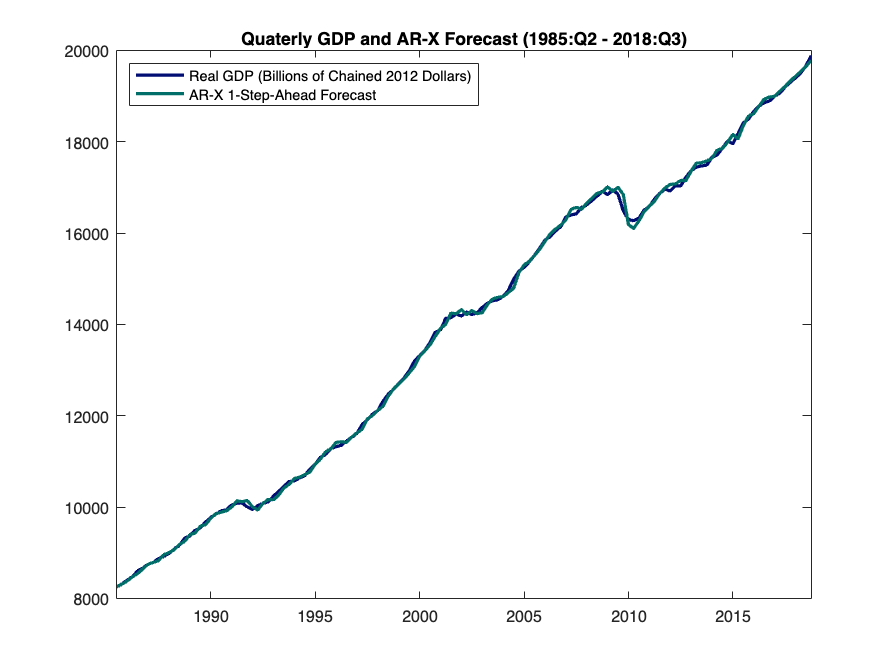

% AR-X GDP forecast plot
clf("reset")
arx_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), arx_forecast, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "AR-X 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and AR-X Forecast (1985:Q2 - 2018:Q3)")
hold off;

## Plots

### y_t:

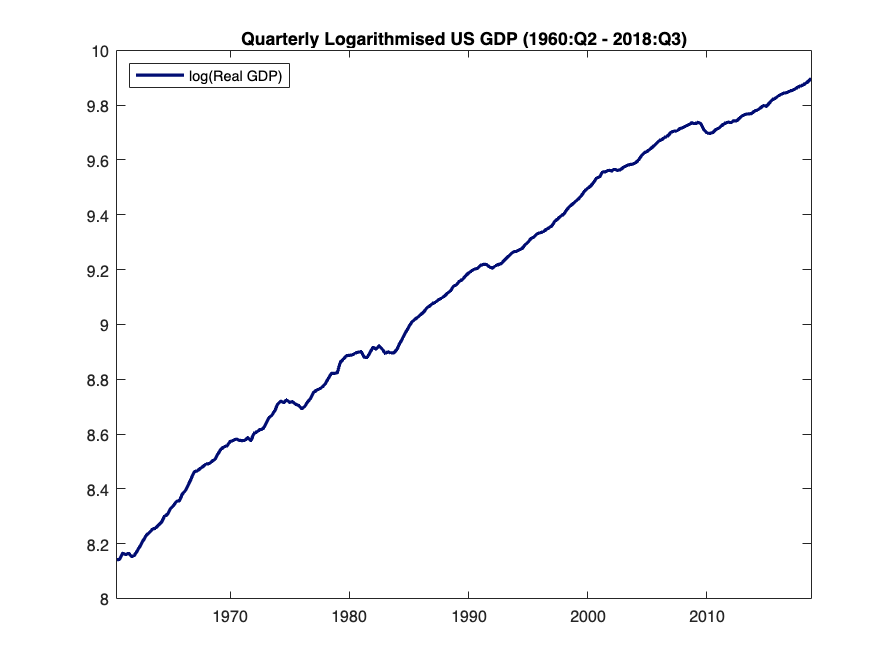

plot_y = plot(data.Time(1:234), data.log_gdp(1:234), "LineWidth",2, color="#010d73");
title("Quarterly Logarithmised US GDP (1960:Q2 - 2018:Q3)");
legend({"log(Real GDP)"}, "Location", "northwest");

### del y_t:

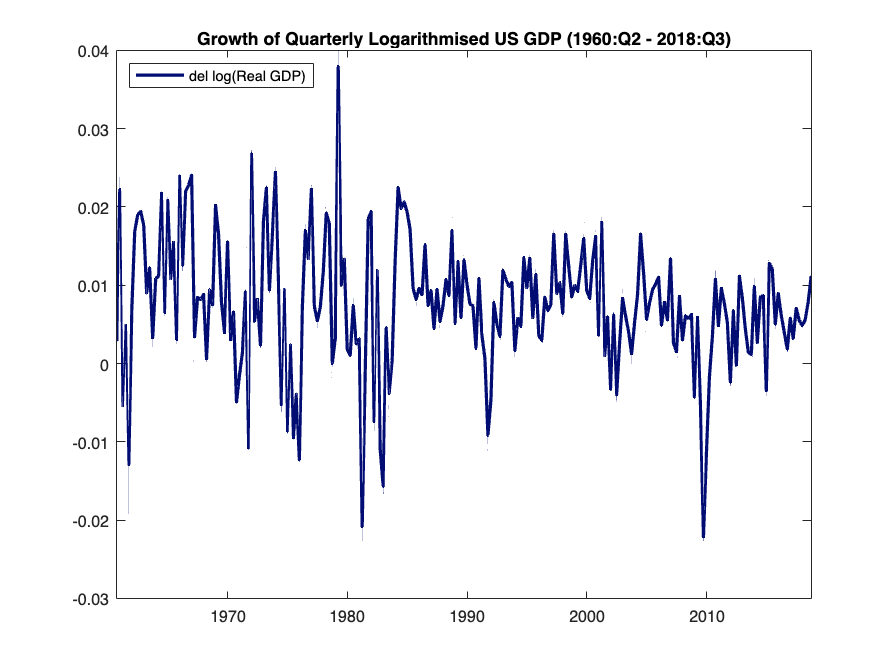

plot_del_y = plot(data.Time(2:234), data.del_y(2:234), "LineWidth",2, color="#010d73");
title("Growth of Quarterly Logarithmised US GDP (1960:Q2 - 2018:Q3)");
legend({"del log(Real GDP)"}, "Location", "northwest");

### log(PCECTPI)

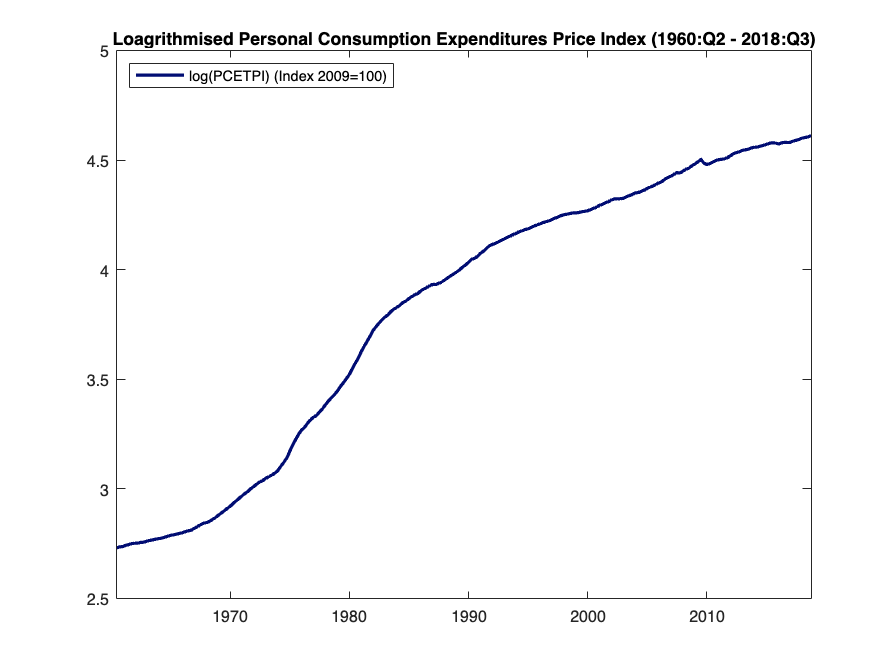

plot_pcectpi = plot(data.Time(1:234), log(data.PCECTPI(1:234)), "LineWidth",2, color="#010d73");
title("Loagrithmised Personal Consumption Expenditures Price Index (1960:Q2 - 2018:Q3)");
legend({"log(PCETPI) (Index 2009=100)"}, "Location", "northwest");

### pi:

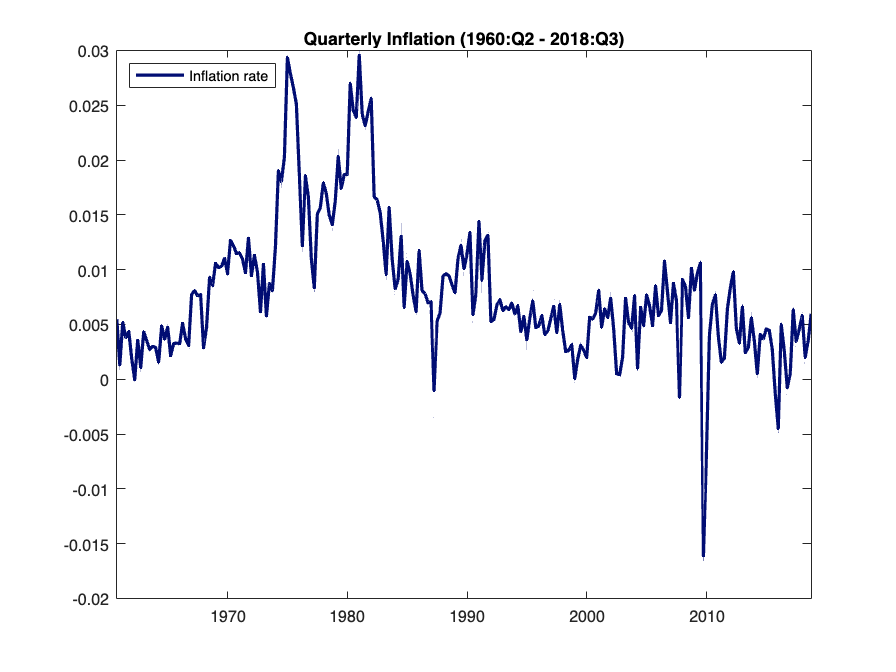

plot_infl = plot(data.Time(2:234), data.infl(2:234), "LineWidth",2, color="#010d73");
title("Quarterly Inflation (1960:Q2 - 2018:Q3)");
legend({"Inflation rate"}, "Location", "northwest");

### Tspread:

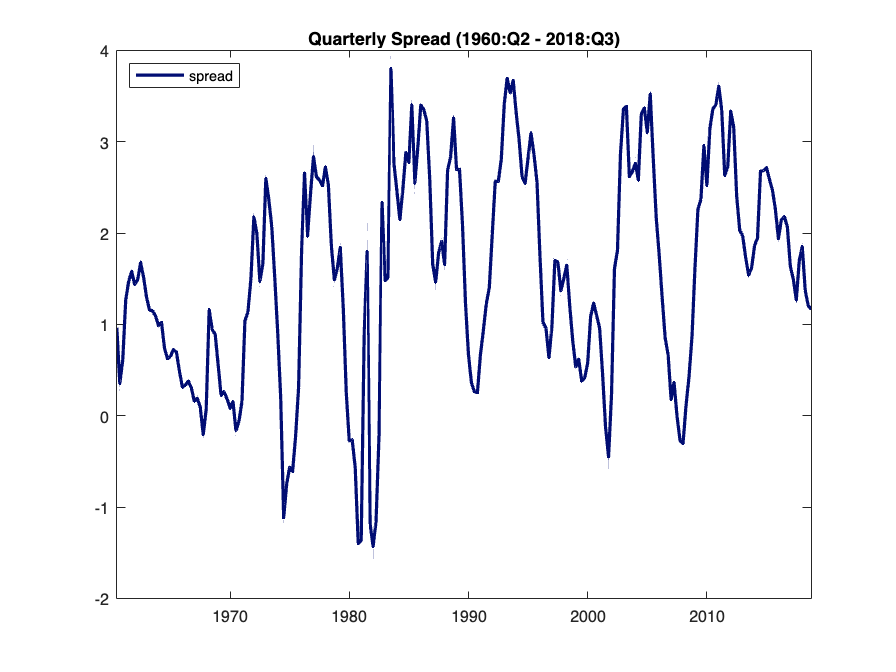

plot_spread = plot(data.Time(1:234), data.spread(1:234), "LineWidth",2, color="#010d73");
title("Quarterly Spread (1960:Q2 - 2018:Q3)");
legend({"spread"}, "Location", "northwest");

## Own model:

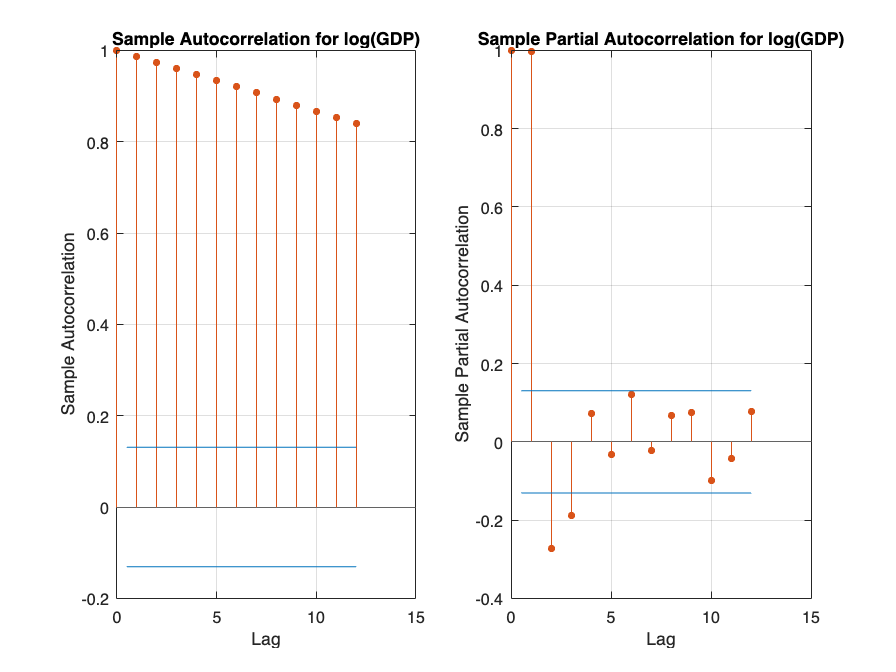

clf("reset")
% ACF of log(GDP)
subplot(1,2,1)
autocorr(data.log_gdp(1:234), NumLags=12)
title("Sample Autocorrelation for log(GDP)")
hold on;
% PACF of log(GDP)
subplot(1,2,2)
parcorr(data.log_gdp(1:234), NumLags=12)
title("Sample Partial Autocorrelation for log(GDP)")

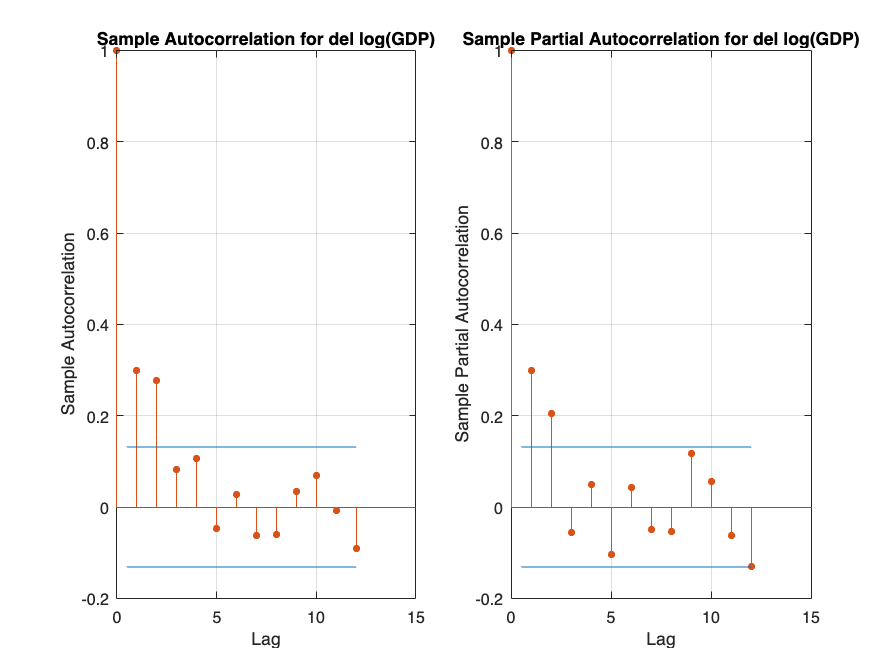


clf("reset")
% ACF of log(GDP)
subplot(1,2,1)
autocorr(diff(data.log_gdp(1:233)), NumLags=12)
title("Sample Autocorrelation for del log(GDP)")
hold on;
% PACF of log(GDP)
subplot(1,2,2)
parcorr(diff(data.log_gdp(1:233)), NumLags=12)
title("Sample Partial Autocorrelation for del log(GDP)")

% Vector to save the forecasts
arima_forecast = NaN(134,1);

% Auxiliary variable for the loop
i = 1;

% Rolling window for forecasting
while i <= 134

    % Model estimation 
    arima_model = estimate(arima(1,1,1), data.log_gdp(i:i+99),"Display","off");
    % 1-step ahead forecast
    arima_forecast(i) = forecast(arima_model,1,data.log_gdp(i:i+99)); 
    % Moving the rolling window
    i = i + 1;

end

% Exponentiation to obtain the level forecast
arima_forecast = exp(arima_forecast);

% RMSE of the level forecast
arima_rmse = rmse(arima_forecast, data.GDPC1(101:234))

arima_rmse =           78.4001160434487


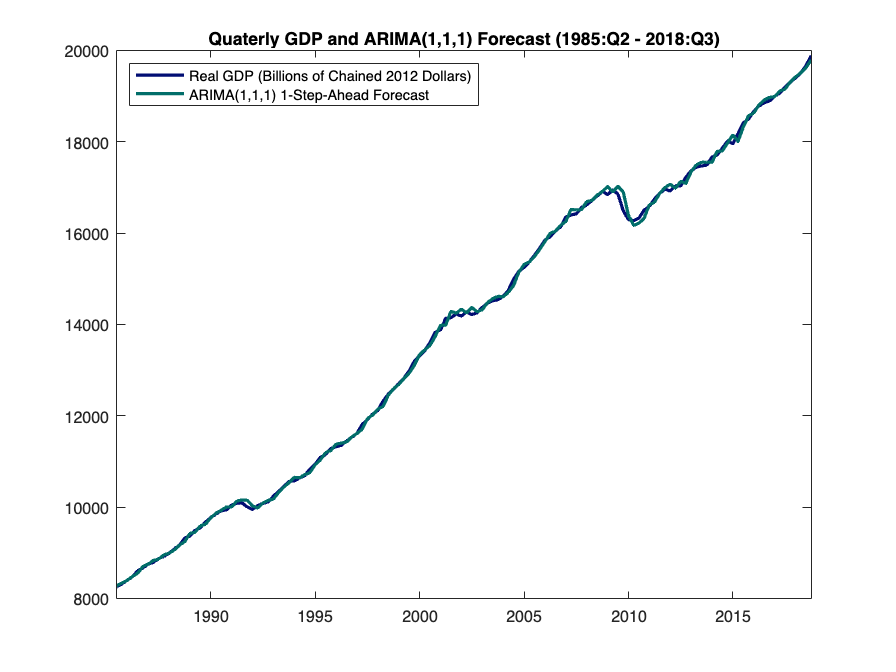

% ARIMA(1,1,1) GDP forecast plot
clf("reset")
arima_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), arima_forecast, "LineWidth",2, color="#026e6a")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "ARIMA(1,1,1) 1-Step-Ahead Forecast"}, "Location", "northwest")
title("Quaterly GDP and ARIMA(1,1,1) Forecast (1985:Q2 - 2018:Q3)")
hold off;

## RMSE Plot

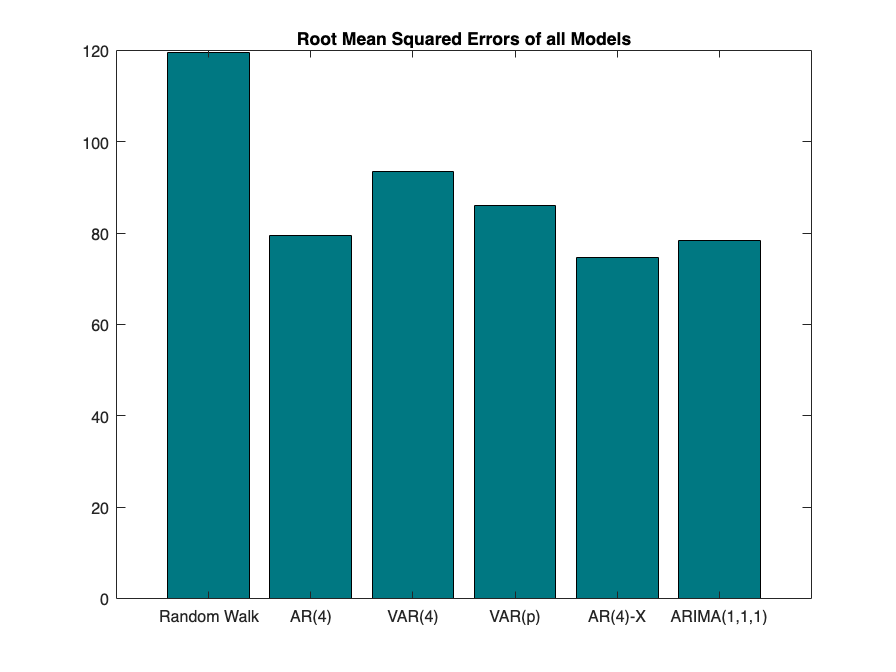

clf("reset")
rmses = [rw_rmse; ar_rmse; var_gdp_rmse; var_p_gdp_rmse; arx_rmse; arima_rmse];
model_names = categorical({'Random Walk', 'AR(4)', 'VAR(4)', 'VAR(p)', 'AR(4)-X', 'ARIMA(1,1,1)'});
model_names = reordercats(model_names, {'Random Walk', 'AR(4)', 'VAR(4)', 'VAR(p)', 'AR(4)-X', 'ARIMA(1,1,1)'});
hb = bar(model_names, rmses);
title("Root Mean Squared Errors of all Models");
set(hb,"FaceColor", [0, 0.471, 0.51]);

## All Forecasts

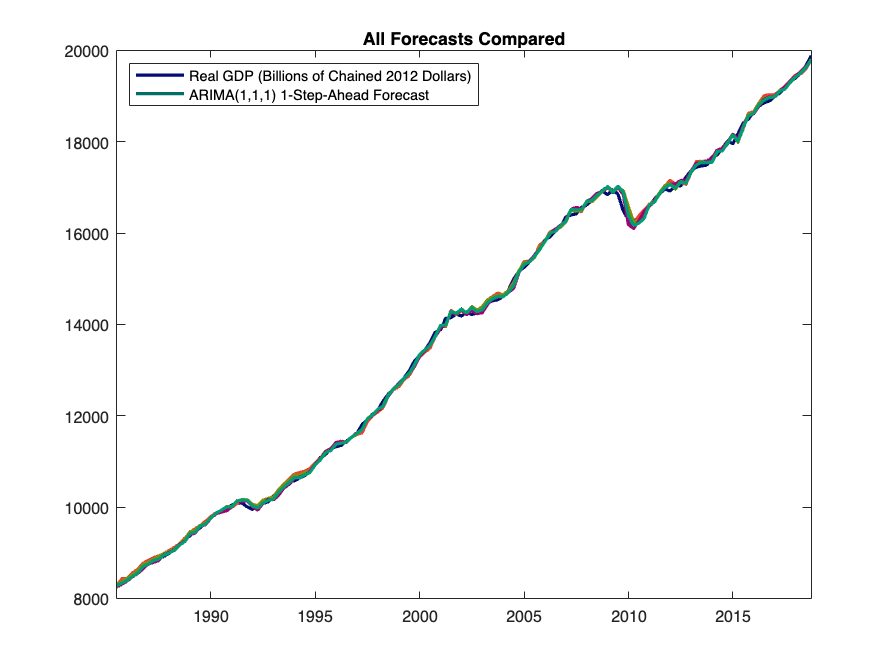

clf("reset")
arx_plot = plot(data.Time(101:234), data.GDPC1(101:234), "LineWidth",2, color="#010d73");
ax = gca; 
ax.YAxis.Exponent = 0;
hold on;
plot(data.Time(101:234), ar_forecast, "LineWidth",2, color="#026e6a")
hold on;
plot(data.Time(101:234), var_forecast_gdp, "LineWidth",2, color="#eb4034")
hold on;
plot(data.Time(101:234), var_p_forecast_gdp, "LineWidth",2, color="#888c0d")
hold on;
plot(data.Time(101:234), arx_forecast, "LineWidth",2, color="#9e0277")
hold on;
plot(data.Time(101:234), arima_forecast, "LineWidth",2, color="#029e72")
legend({"Real GDP (Billions of Chained 2012 Dollars)", "ARIMA(1,1,1) 1-Step-Ahead Forecast"}, "Location", "northwest")
title("All Forecasts Compared")
hold off;